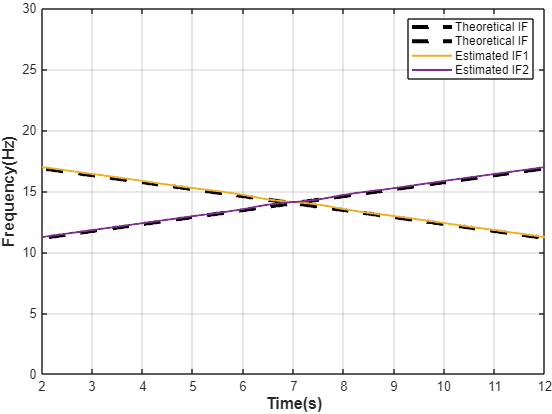

% example of improved dual spectral centroid method based on SCT frequency operator. 

%  This program is free software; you can redistribute it and/or modify
%  it according to your requirement.
%
%  This program is distributed in the hope that it will be useful,
%  but WITHOUT ANY WARRANTY; without even the implied warranty of
%  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  
%
%   Written by Xu Yan in Xidian University at 2025.05.15.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Signal Settings %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all; close all;
Hz = 100 ; % sampling rate
L = 14 ; % time duration in second

t = [1/Hz:1/Hz:L]' ;
f1 = 18;  %(14~28)
k1 = (14-f1)/7;
k2 = -k1;
f2 = 14-7*k2;
x1 = exp(2*pi*1i*((k1/2)*t.^2 + f1*t)) ;
x2 = exp(2*pi*1i*((k2/2)*t.^2 + f2*t)) ; 
x = x1 + x2; % input signal
x = awgn(x,15,"measured");

tt = -L:1/Hz:L;

% different windows
alpha1 = 1;
h1 = exp(-pi*alpha1*tt.^2'); % window g_0
Dh1 = dwindow(h1);
DDh1 = dwindow(Dh1);
lowFreq = 0;
highFreq = 0.5;
alpha = 2/600;  % adjust the resolution here.
tDS = 1;
h = h1;
Dh = Dh1;
% DDh = DDh1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Time-frequency Matrix Parameter Settings %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[xrow,xcol] = size(x) ;
t = [1:length(x)] ;
tLen = length(t(1:tDS:length(x))) ;

% for tfr
N = length([-0.5+alpha:alpha:0.5]) ;
crate = ([1:N-1]-ceil(N/2))/N^2; % discretization of chirp rate

% for tfrsq
Lidx = ceil( (N/2)*(lowFreq/0.5) ) + 1 ;
Hidx = floor( (N/2)*(highFreq/0.5) ) ;
fLen = Hidx - Lidx + 1 ; % number of bins of frequency
cLen = length(crate); % number of bins of chirp rate
%====================================================================
%% check input signals
if (xcol~=1)
    error('X must have only one column');
elseif highFreq > 0.5
    error('TopFreq must be a value in [0, 0.5]');
elseif (tDS < 1) || (rem(tDS,1))
    error('tDS must be an integer value >= 1');
end

[hrow,hcol] = size(h); Lh = (hrow-1)/2;
if (hcol~=1)||(rem(hrow,2)==0)
    error('H must be a smoothing window with odd length');
end
ht = [-Lh:Lh] ;

%====================================================================
%% run STFT and reassignment rule
tfc = zeros(N-1, N/2, tLen); 	% chirplet transform
tfrsq = zeros(cLen, fLen, tLen); % synchrosqueezed chirplet transform

tfrtic = linspace(0, 0.5, N/2)' ; % positive frequency
tcrtic = crate;
tfrsqtic = linspace(lowFreq, highFreq, fLen)' ;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%In this article, this section shows the frame-by-frame serial input of the λ classification results; 
%since this document does not cover the algorithm details of the classification part, 
% the neighborhood of the true λ position is used as the input.

lambda_search1 = [142:148]; % λ for signal 1  
lambda_search2 = [152:158]; % λ for signal 2                       

lambda_search = [lambda_search1 lambda_search2];
df = tfrtic(2)-tfrtic(1);
omega_esti_final = zeros(2,tLen);

for tidx = 1:tLen

    omega_esti_final1 = 0;
    omega_esti_final2 = 0;

    for cidx = lambda_search 

        chirp = crate(cidx);

        % ti is the current time
        ti = t((tidx-1)*tDS+1);
        % tau is the relevant index associated with ti
        tau = -min([round(N/2)-1,Lh,ti-1]):min([round(N/2)-1,Lh,xrow-ti]);
        % indices is the absolute index in the "evaluation window"
        indices= rem(N+tau,N)+1;

        tf0 = zeros(N, 1) ; tf1 = zeros(N, 1) ; tf2 = zeros(N, 1) ;
        tfx0 = zeros(N, 1) ; tfx1 = zeros(N, 1) ; tfx2 = zeros(N,1);

        tf0(indices) = x(ti+tau).*conj(h(Lh+1+tau)).*exp(-pi*1i*chirp.*...
            (ht(Lh+1+tau)').^2); % for CT with window g
        tf1(indices) = x(ti+tau).*conj(Dh(Lh+1+tau)).*exp(-pi*1i*chirp.*...
            (ht(Lh+1+tau)').^2); % for CT with window g'
        tfx0(indices) = x(ti+tau).*conj(h(Lh+1+tau)).*ht(Lh+1+tau)'.*...
            exp(-pi*1i*chirp.*(ht(Lh+1+tau)').^2); % for CT with window xg

        % select nonnegative frequencies
        tf0 = fft(tf0) ; tf0 = tf0(1:N/2) ;
        tf1 = fft(tf1) ; tf1 = tf1(1:N/2) ;
        tfx0 = fft(tfx0) ; tfx0 = tfx0(1:N/2) ;
        % search the max omega

        tf0_norm = abs(tf0)/max(abs(tf0));
        po_peaks = find(tf0_norm == 1);

        % % compute the reassignment rules

        if ismember(cidx,lambda_search1)==1
            po_lambda_max = [-500*ones(1,po_peaks-1) (145+round(4*rand-2))*ones(1,10) -500*ones(1,max(150-po_peaks-9,0))]';% λ^*_m for signal 1 
            lambda = po_lambda_max-ceil(N/2);
            lambda0 = lambda/N^2;
            omega = N * imag(tf1./tf0./(2.0*pi) - (chirp*1i-(imag(lambda0)+1i*imag(lambda0))).*tfx0./tf0);
            omega_esti = (1:N/2)'- omega;
            omega_esti_final1 = omega_esti_final1 + (omega_esti(po_peaks)*df-df)*Hz;
        else
            if po_peaks-1>140
            po_lambda_max = [-500*ones(1,po_peaks-5) (155+round(4*rand-2))*ones(1,max(150-po_peaks+5,0))]'; % λ^*_m for signal 2 
            else
                po_lambda_max = [-500*ones(1,po_peaks-1) (155+round(4*rand-2))*ones(1,10) -500*ones(1,max(150-po_peaks-9,0))]';
            end
            lambda = po_lambda_max-ceil(N/2);
            % lambda = round(N^2 * imag(lambda0));
            lambda0 = lambda/N^2;
            omega = N * imag(tf1./tf0./(2.0*pi) - (chirp*1i-(imag(lambda0)+1i*imag(lambda0))).*tfx0./tf0);
            omega_esti = (1:N/2)'- omega;
            omega_esti_final2 = omega_esti_final2 + (omega_esti(po_peaks)*df-df)*Hz;
        end

    end
    omega_esti_final(1,tidx) = omega_esti_final1/length(lambda_search1); 
    omega_esti_final(2,tidx) = omega_esti_final2/length(lambda_search2); 
end
figure
t = [1/Hz:1/Hz:L]' ;
if1 = f1+k1*t;
if2 = f2+k2*t;
plot(t,if1,'k--',t,if2,'k--','LineWidth',3);
ylim([0 30])
xlim([2 12])
hold on
plot(t,smooth(omega_esti_final(1,:),100),t,smooth(omega_esti_final(2,:),100),'LineWidth',1.5);
grid on
xlabel('Time(s)','FontSize',12,'FontWeight','bold');
ylabel('Frequency(Hz)','FontSize',12,'FontWeight','bold');
legend('Signal 1', 'Signal 2','decision plane');
hold off;
legend('Theoretical IF','Theoretical IF','Estimated IF1','Estimated IF2');
set(gca,'LooseInset',get(gca,'TightInset'));

esti = (mean(abs(omega_esti_final(2,200:400)-if2(200:400)'))+mean(abs(omega_esti_final(1,200:400)-if1(200:400)')))/2

esti = 0.0970